# Definition of Derivatives

How much time do you have to drink your coffee before it becomes too cold? How far will a ball travel before it hits the ground? Will my couch fit through the hallway into my apartment? Many every-day interactions can be described by functions, and these functions can be analyzed by studying their rates of change.

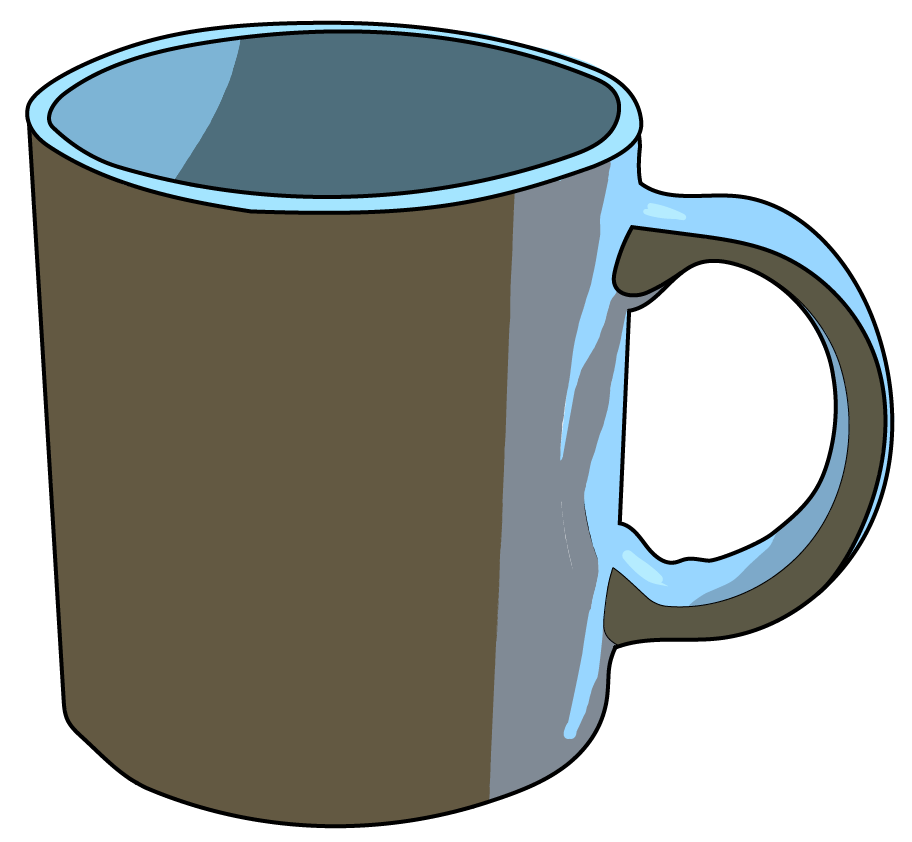             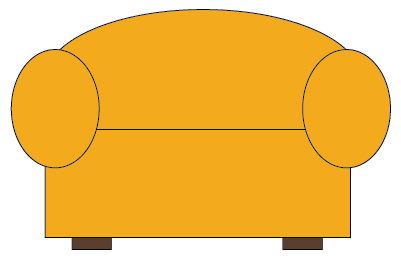            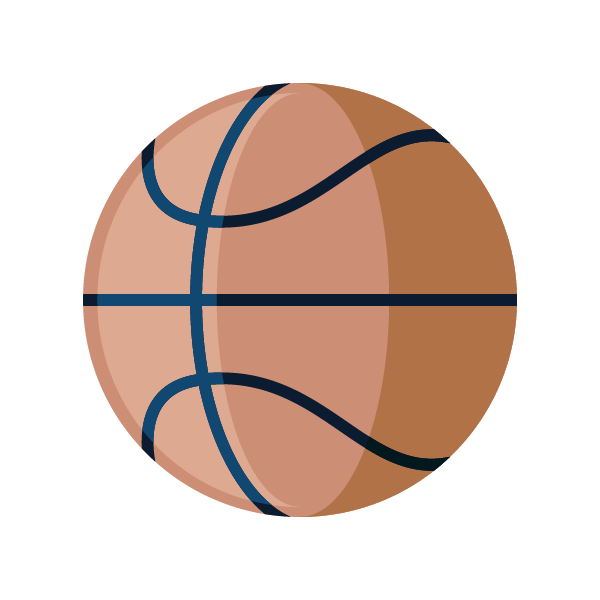

Derivatives allow us to answer these questions by computing rates of change for a given function. 

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

## Definition of the Derivative

The derivative of a function tracks the rate of change of that function at each point in its domain. 

#### Motivating Example: Cooling Coffee

Consider the function $T(t)$ that tracks the temperature, in degrees Celsius, of a cup of coffee as a function of time, in minutes. If the coffee is poured out of a temperature-controlled carafe held at $95^{\circ}$C at $t=5$ minutes, a representative cooling curve is presented below. The rate of change of $T(t)$ with respect to time $t$ in this scenario is the rate at which the coffee is cooling, with units of degrees Celsius per minute. Calculus provides tools that can determine the rate of change at each point of this function. 

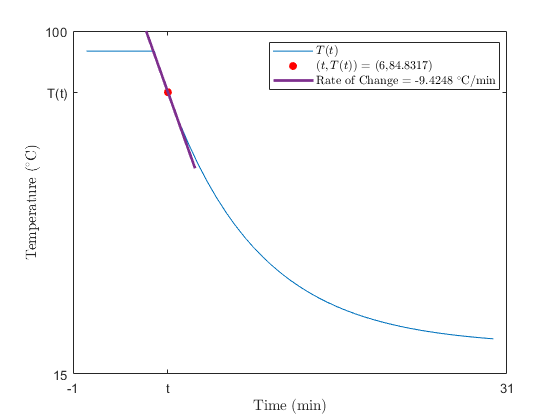

t1 = 6;   % Select a point to evaluate T(t) at, default t1 = 6
syms t;                             % Create a symbolic variable
                    % Run this section
if ~exist("sCoffee","var")||~isvalid(sCoffee)
    figure                          % Initialize a figure
    [sCoffee,tHandle,Temp] = coffeeExample(t1); % Run the function coffeeExample found in Helper Functions
end
sCoffee.XData = t1;                         % Reset the x coordinate of the point
T1 = Temp(t1);                              % Evaluate the point T1 = T(t1)
sCoffee.YData = T1;                         % Reset the y coordinate of the point
tHandle.XData = [t1-2,t1+2];                % Reset the x data for the linear approximation
[m,tempApprox] = getLinApprox(Temp,t,t1);   % The function getLinApprox is defined in Helper Functions
tHandle.YData = tempApprox([t1-2,t1+2]);    % Reset the y data for the linear approximation
ax = sCoffee.Parent;                           % Track the axis plotting the coffee curve
xticks(ax,[-1 t1 31]);                         % Add an x tick at the point t=x1
yticks(ax,[15 double(T1) 100]);                % Add a y tick at the point T=T1
legend(ax,["$T(t)$" "$(t,T(t))$ = ("+t1+","+double(T1)+")" "Rate of Change " + ...
    "= "+m+" $^{\circ}$C/min"],"Location","best","Interpreter","latex")

drawnow

#### Motivating Example: Basketball

The height of a basketball $H$, in meters, as a function of the time $t$, in seconds has a derivative that tracks the rate of change of height with respect to time in meters per second. The derivative of a position function with respect to time is a velocity function. The derivative of a velocity function with respect to time is an acceleration function.

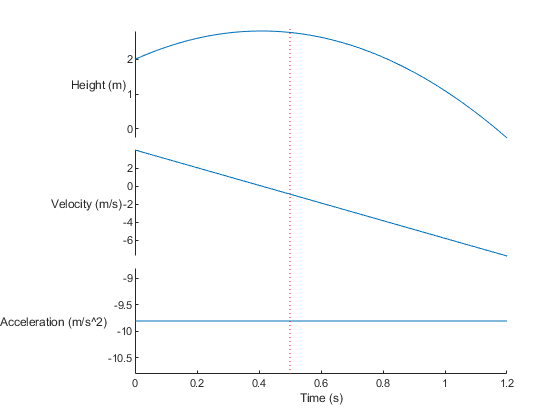

t2 = 0.5;  % Select the point in time to consider
               % Run this section
if ~exist("lH","var") || ~isvalid(lH) 
                                  % Check if this section has been run before, if not set up the graph
    figure 
    lH = basketballExample(t2);   % Run the function basketballExample found in Helper Functions
else
xloc = .9061-.1331*(5-25/6*t2);   % Scale the x value for the line to the plot window inside the figure window
lH.X = [xloc xloc];               % Update the location of the red dotted line
end

#### Motivating Example: Moving a couch

Consider moving a couch into a new apartment. It may be necessary to maneuver the couch around a corner, but couches are not flexible. Calculus offers tools to determine whether a one-dimensional couch will fit around a corner. Calculus provides a method that will locate the minimal value of the longest path over all possible paths around a curve. Similar methods could be employed for a more realistic three dimensional couch.

The black lines model the walls, the white area is the available floor and the red line models the couch.

           % This button runs this section of code
figure
couchExample([1.5 9]);  % Run the function couchExample found in Helper Functions

### Limit Definition of the Derivative

More formally, the derivative of a function $y=f(x)$ is defined as the limit of the slopes of secant lines between the points $(x,f(x))$ and $(x+h,f(x+h))$:


$$f'(x) = \lim_{h \rightarrow0} \enspace\frac{f(x+h) - f(x)}{h}$$
 

#### Illustrative Example

Let $f(x) = x^2$, and choose a particular value $x_1=-1$, and start with $h=2.5$. Observe the slope of the secant line as you make $|h|$ smaller.

syms x            % Set up a symbolic variable x
f(x) = x^2;       % Define a function f(x) = x^2
x1 = -1;          % Set the initial value x=x1 to be -1
h = 2.5;     % Select the step size h
figure
 
fplot(f(x))       % Plot the function y=f(x) using the symbolic function plotting command
hold on
title("Plotting the secant line between $x = $" + x1 + " and $x+h = $" + x1+h,"Interpreter","latex")
xlabel("x")
ylabel("f(x)")
graphSecant(@(x)f(x),x1,x1+h,"f");                        % graphSecant is a function in Helper Functions
legend(["" "$f(x)$" "Secant line from $x_1$ to $x_1+h$"],"Location","north")
m = double((f(x1+h)-f(x1))/(h));                          % Compute the slope of the secant line
annotation("textbox",[.4 .5 .2 .2],"EdgeColor","w","String","slope = "+m) % Display the slope on the plot


$$\text{Slope}  = \frac{f(-1+h)-f(-1)}{h} = \frac{(-1+h)^2-(-1)^2}{h} = \frac{1-2h+h^2-1}{h} = -2+h$$


The derivative of the function $f(x)$ at the point $x=x_1$ is


$$f'(x_1) = \lim_{h\to 0} \frac{f(x_1+h)-f(x_1)}{h} = \lim_{h\to 0} -2 + h = -2$$


fplot(f(x))           % Plot y=f(x) using the symbolic graphing function
dx = 0;               % Set a step size of 0 to reuse the secant code to graph a tangent line
hold on
title("Plotting the tangent line to $f(x) = x^2$ at $x_1 =$" + x1,"Interpreter","latex")
xlabel("x")
ylabel("f(x)")
graphSecant(@(x)f(x),x1,x1+dx,"f");  % graphSecant is defined in Helper Functions
hold on
scatter([x1 x1+dx],double([f(x1) f(x1+dx)]),"ro","filled")                % Plot (x1,f(x1))
legend(["" "$f(x)$" "Tangent line at $x_1$"],"Location","north","Interpreter","latex")
m = 2*x1;            % Compute the slope of the tangent line to x^2 at x=x1
annotation("textbox",[.4 .5 .2 .2],"EdgeColor","w","String","slope = "+m) % Display the slope on the plot
hold off

The line through a point on a curve with a slope equal to the derivative at that point is called the tangent line. It is the best linear approximation to the function at that point.    

Putting this all together:


$$f'(x) = \lim_{h \rightarrow0} \enspace\frac{f(x+h) - f(x)}{h}= \lim_{\Delta x \to 0} \frac{\Delta f}{\Delta x} = \lim_{(x_2-x_1) \to 0} ~\frac{y_2 - y_1}{x_2-x_1}$$


The ratio $\frac{f(x+h)-f(x)}{h}$ is called the difference quotient.

### Derivatives as Limits of Secant Lines

  **Try. **

First, use the default function to set up a graphical representation of the limit definition. Then try a few more functions of your choice.

syms x f(x) h df dx              % set up symbolic variables and functions
f(x) =  x^3      % define the function and display the result

  **Pro-tip**. MATLAB syntax is `3*x^2` for $3x^2$ or `exp(2*x)` for $e^{2x}$. For more detail, check out the Help Center documentation for [mathematical functions](https://www.mathworks.com/help/matlab/referencelist.html?type=function&listtype=cat&category=mathematics) or the [Basic Functions Reference](https://www.mathworks.com/content/dam/mathworks/fact-sheet/matlab-basic-functions-reference.pdf).

                 % Run the current section
figure                            % Initialize a figure
x1 = 1; % Define a value for x1
fx1 = f(x1);                      % Compute the value f(x1)
fplot(f(x), "k")                  % Plot y=f(x) using the symbolic function plotter
hold on
scatter(x1,f(x1),"r","Filled")    % Plot (x1,f(x1)) on the graph
x2 = -4; % Define a value for x2
out = graphSecant(@(x) f(x),x1,x2,"f");  % graphSecant is defined in Helper Functions
                                  % out is true if x1-x2 = 0
if out                            % Run if x1-x2 = 0 to highlight the secant/tangent difference
    warning("There is no secant line through a single point. Graphing the tangent line.")
end

**Calculations:**

Use $h$`=x2-x1` for the step size $\Delta x$:

deltax = x2-x1;    % Compute h = x2-x1, the denominator of the difference quotient
% Print the steps of the computation
displayFormula("h = deltax")
if deltax ~= 0                       % Separate secant and tangent computations
    fx2 = f(x2);                     % Compute the value f(x2)
    df21 = fx2-fx1;                  % Compute f(x2)-f(x1), the numerator of the difference quotient
    sDQ = simplify(df21/deltax);     % Symbolically simplify the difference quotient
    vpaDQ = vpa(sDQ);                % Express the difference quotient in variable precision arithmetic
    displayFormula("f(x_1+h)-f(x_1) = f(x2)-f(x1)")
    displayFormula("f(x_1+h)-f(x_1) = fx2-fx1")
    displayFormula("(f(x_1+h)-f(x_1))/h = sDQ")
    if ~isequal(round(sDQ),sDQ)
        displayFormula("(f(x_1+h)-f(x_1))/h = vpaDQ")
    end
else
    fxph = f(x+h);                   % Name the symbolic expression f(x+h)
    fx = f(x);                       % Name the symbolic expression f(x)
    displayFormula("df/dx = limit((fxph-fx)/h,h,0)")
    dfEval(x) = diff(f(x),x);        % Compute the symbolic derivative f'(x)
    dfxS = simplify(dfEval(x1));     % Evaluate and symbolically simplify f'(x1)
    dfxV = vpa(dfxS);                % Express f'(x1) in variable precision arithmetic
    displayFormula("df/dx = dfxV")
end

  **Try **

Investigate what happens for different values of `x1` and `x2` and for different functions `f(x)`.  

 **Reflect**

- What do you notice about the slope of the secant line as you change `x2`?

- What happens when you set `x2` equal to `x1`?

- Can you find values for `x1` and `x2` where the secant line has a positive slope? Or negative slope? Or zero slope? 

- Do your answers to Question 3 change if you start with a different function `f(x)`?

## Derivatives are Slopes

Using the fact that the derivative is the slope of the tangent line, try evaluating the definition of the derivative at different points. Notice that when the derivative is positive, the function is increasing (and vice versa). The function you are exploring here is $y = 6 + \cos(x) - \frac{32}{5}e^{-x/5}$ over a range from $x=0$ to $x=25$. 

xPosn = 3;  % Set the value of x to consider
figure
exampleFunction(xPosn);             % exampleFunction is defined in Helper Functions
                          % Run this section

 **Reflect**

- What do you notice about the derivative near the top of a peak? What about near the bottom of a valley? 

- Can you calculate the derivative of this function from its limit definition? Why or why not?

## **Graphical Derivatives**

Surprisingly often, it is sufficient to know the sign (positive, negative, or zero) of a derivative. A positive derivative at a point means the function is increasing in value from left to right at that point. A negative value means the function is decreasing in value from left to right at that point. And a zero derivative means the function is constant, neither increasing nor decreasing, in value at that point.

syms x                             % Create the symbolic variable x
g(x) =  exp(x)*cos(x)+x^2        % Define a function g(x)
xa = -3;  % Select a point x=xa
                         % Run this section of code
figure 
fplot(g,"k");                      % Symbolically plot the function y=g(x)
hold on
scatter(xa,g(xa),"r","filled")    % Plot the point (xa, g(xa))
hold off
title("Plot of $y = g(x)$ and the point $(x_1, g(x_1))$ = (" + xa + "," + double(g(xa)) + ")","Interpreter","latex")
xlabel("$x$","Interpreter","latex")
ylabel("$g(x)$","Interpreter","latex")

** Exercise 1**. Determine the sign of the derivative at the point you have selected:

slope = "positive";       % Set the value of slope from a set of options
                         % Run this section
if ~exist("xa","var")               % Check whether the variable xa exists
    xa = 3;                         % If not, set xa to its default value
end
if ~exist("g","var")                % Check whether the function g(x) exists
    syms x
    g(x) = exp(x)*cos(x)+x^2;       % If not, set g(x) to its default value
end
checkSlope(slope,@(x) g(x),xa,"g"); % The function checkSlope is defined in Helper Functions

** Exercise 2**. Find a point on the graph that has the specified derivative:

                     % Run this section
syms x                          % Create the symbolic variable x
figure                          % Initialize a figure
q(x) = piecewise( ...           % Define a piecewise function q(x)
    x < -1, 5-(x+3)^2, ...      % if x < -1, q(x) = 5-(x+3)^2
    x < 2, -x, ...              % if -1 <= x < 2, q(x) = -x
    x < 4, -2, ...              % if -2 <= x < 4, q(x) = -2
    (x-4)^3-2);                 % if x >= 4, q(x) = (x-4)^3-2
p = fplot(q(x),"LineWidth",1);  % Symbolically plot the function y=q(x)
ylim([-3 6])                    % Set the y limits to strictly contain the maximum and minimum values of y=q(x)
xticks(-5:5)                    % Show x ticks at each integer value
xlabel("x")
ylabel("y")
title("Graph for Exercise 2")
grid on                         % Turn on the grid to allow easy analysis of the graph

Identify each point by its `x` value.

1. Identify a point with `x<0` where the derivative is positive.

q1 = -6;     % Solicit user input as x = q1
if (q1 < -5) || (q1 > 5)       % Check if q1 is not in the defined domain, [-5,5]
    disp("Please select a value between -5 and 5.")
elseif (q1 > -5) && (q1 < -3)  % Check if q1 is in (-5,-3)
    disp("Correct.")
elseif q1 == -5                % Check if q1 is on the boundary
    disp("You cannot be sure what the derivative is at the boundary of a plot without additional information.")
elseif q1 > 4                  % Check if q1 is positive and in a region with positive derivative
    disp("This is not a point with x<0.")
else                           % General incorrect answer
    disp("Incorrect. Please try again.")
end

2. Identify a point with `x>0` where the derivative is positive.

q2 = 6;     % Solicit user input as x = q2
if (q2 < -5) || (q2 > 5)       % Check if q2 is not in the defined domain, [-5,5]
    disp("Please select a value between -5 and 5.")
elseif (q2 > -5) && (q2 < -3)  % Check if q2 is negative and in a region with positive derivative
    disp("This is not a point with x>0.")
elseif q2 == 5                 % Check if q2 is on the boundary
    disp("You cannot be sure what the derivative is at the boundary of a plot without additional information.")
elseif q2 > 4                  % Check if q2 is in (4,5)
    disp("Correct.")
else                           % General incorrect answer
    disp("Incorrect. Please try again.")
end

3. Identify a point with `x<0` where the derivative is negative.  

q3 = -6;     % Solicit user input as x = q3
if (q3 < -5) || (q3 > 5)       % Check if q3 is not in the defined domain, [-5,5]
    disp("Please select a value between -5 and 5.")
elseif (q3 > -3) && (q3 < 0) && (q3 ~= -1)  
                               % Check if q3 is negative and in a region with negative derivative
    disp("Correct.")
elseif q3 == -1                % Check if q3 is a critical point
    disp("The derivative does not exist at this point. Please try again.")
elseif (q3 >= 0) && (q3 < 2)   % Check if q3 is positive and in a region with negative derivative
    disp("This is not a point with x<0.")
else                           % General incorrect answer
    disp("Incorrect. Please try again.")
end

4. Identify a point with `x>0` where the derivative is negative.  

q4 = 6;         % Solicit user input as x = q4
if (q4 < -5) || (q4 > 5)           % Check if q4 is not in the defined domain, [-5,5]
    disp("Please select a value between -5 and 5.")
elseif (q4 > 0) && (q4 < 2)        % Check if q4 is positive and in a region with negative derivative
    disp("Correct.")
elseif (q4 > -3) && (q4 <= 0) && (q4 ~= -1)  
                                   % Check if q4 is negative and in a region with negative derivative
    disp("This is not a point with x>0.")
else                               % General incorrect answer
    disp("Incorrect. Please try again.")
end

5. Identify a point with `x<0` where the derivative is zero.

q5 = -6;    % Solicit user input as x = q5
if (q5 < -5) || (q5 > 5)      % Check if q5 is not in the defined domain, [-5,5]
    disp("Please select a value between -5 and 5.")
elseif q5 == -3               % Check if q5 is an extremum
    disp("Correct.")
elseif (q5 > 2) && (q5 <= 4)  % Check if q5 is positive and in a region where the derivative is zero
    disp("This is not a point with x<0.")
else                          % General incorrect answer
    disp("Incorrect. Please try again.")
end

6. Identify a point with `x>0` where the derivative is zero.

q6 = 6;    % Solicit user input as x = q6
if (q6 < -5) || (q6 > 5)      % Check if q6 is not in the defined domain, [-5,5]
    disp("Please select a value between -5 and 5.")
elseif (q6 > 2) && (q6 <= 4)  % Check if q6 is positive and in a region with derivative 0
    disp("Correct.")
elseif q6 == -3               % Check if q6 is negative and has derivative 0
    disp("This is not a point with x<0.")
else                          % General incorrect answer
    disp("Incorrect. Please try again.")
end

7. Identify two different points, `x1` and `x2`  in the interval (-5,5), where the derivative does not exist.

q71 = -6;                                  % Solicit user input as x = q71
q72 = 6;                                  % and x = q72
if (q71 < -5) || (q71 > 5) || (q72 < -5) || (q72 > 5)        % Check if the values are in the defined domain
    disp("Please select values between -5 and 5.")
elseif (q71 == -1 && q72 == 2) || (q71 == 2 && q72 == -1)    % Check if the values are correct
    disp("Correct.")
elseif (q71 == -1) || (q72 == -1)                            % Check if only one correct value has been found
    disp("Yes, the derivative does not exist at the point x = -1, but what about the second point?")
elseif (q71 == 2) || (q72 == 2)                              % Check if only one correct value has been found
    disp("Yes, the derivative does not exist at the point x = 2, but what about the second point?")
else                                                         % General incorrect answer
    disp("Incorrect. Please try again.")
end
  % Run this section to generate feedback on all the solutions at once, all default answers are outside [-5,5]

 **Reflect**

- How easy is it to find points where the derivative is zero? Do they exist on your graph? Why or why not?

- What does knowing the sign of the derivative tell you about your function?

- Using + for regions with a positive derivative, - for regions with a negative derivative, and 0 for regions where the derivative is zero, can you sketch two or more functions with derivatives that fit different patterns? How about + everywhere? Or -0+? Or +0-0+? Perhaps -0-? 

- Can you sketch a function with a derivative that is -+ and never 0? Why or why not? 

#### Derivative as an Operator

The derivative can be thought of as an operator $\frac{d}{dx}$ which acts on one function $f(x)
$ using it to produce a new function $\frac{df}{dx}$ that tracks the rate of change of the original function at each point. Alternatively, you can think of the derivative as a black box which accepts a function as input and returns a new, but related, function as output, similar to some visualizations of functions themselves:

For a function, the input $x$ is transformed to an output $f(x)$:

For a derivative, the input $f(x)$ is transformed to an output $\frac{df}{dx}$ which can also be written as $f'(x)$:

 

## Notes on Notation

You may see the derivative of a function represented using different notation. 

Notation:                        Read As:

         $f'(x)$                     "eff prime of ex", 

           $\frac{df}{dx}$                         "dee eff dee ex",

             $\frac{d}{dx}[f(x)]$            "dee dee ex of eff of ex",

While they may appear different, all of these notations mean the same thing: the derivative of a function $f(x)$ with respect to the variable $x$. 

While the function f and x were chosen for this example, you can extend this notation to any function and variable! For example, the derivative of the function g with respect to the variable z (in its notations corresponding to above) would look like:


$$g'(z), \enspace \frac{dg}{dz},\enspace\frac{d}{dz}[g(z)]$$


There is a subtle difference in notation between $f'(x), \enspace \frac{df}{dx} \enspace$ and  $\frac{d}{dx}[f(x)]$. The former describe functions which are the result of applying the derivative operator to a function. The notation $f'(x)$ is called "prime notation" and is primarily used as a shorthand when there is only one independent variable and especially when the derivative is going to be evaluated at specific points, such as $f'(a)$ to describe the slope of the function $f(x)$ at the point $x=a$. The latter references the act of taking a derivative of a function. In this sense, the latter notation refers to the derivative as an "operator" where it "operates/acts" on the original function. 

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function [sP,cTan,T] = coffeeExample(x1)
% This example creates the graph of the cooling coffee example
% T(t) was defined using Newton's law of cooling applied to a liquid stored in a 95 degree
% temperature-controlled environment up to t = 5 then moved to a 22 degree temperature-controlled
% environment and allowed to equilibrate. The time constant was estimated
% to approach the author's experience
syms t      % Set up the symbolic variable t
T(t) = piecewise(t<5,95,73*exp(-.15*(t-5))+22);  % Define the symbolic piecewise temperature function T(t)
y1 = double(T(x1));  % Compute T(x1) as a number
[m,linApprox] = getLinApprox(T,t,x1);  % The function getLinApprox is defined in Helper Functions
fplot(T,[0 30]);   % Symbolically plot the temperature over 30 minutes
hold on
sP = scatter(x1,y1,'r','filled'); % Add a point at (x1,T(x1))
cTan = plot([x1-2,x1+2],linApprox([x1-2,x1+2]),"Color",[0.4940 0.1840 0.5560],"LineWidth",2); % Purple
hold off
ylim([15 100])             % Choose y limits for a reasonable viewing window
xlim([-1 31])              % Choose x limits for a reasonable viewing window
xlabel("Time (min)","Interpreter","latex")
ylabel("Temperature ($^{\circ}$C)","Interpreter","latex")
xticks([-1 x1 31]);       % Add an x tick at the point t=x1
yticks([15 y1 100]);      % Add a y tick at the point T=y1
xticklabels(["-1" "t" "31"])
yticklabels(["15" "T(t)" "100"])
legend(["$T(t)$" "$(t,T(t))$ = (" + x1 + "," + y1 + ")" "Rate of Change = " ...
    + m + " $^{\circ}$C/min"],"Location","best","Interpreter","latex")
end

function [m,linApprox] = getLinApprox(y,x,a)
% getLinApprox creates a tangent line function to y(x) at the point x=a
%
% getLinApprox requires four arguments
%   y a symbolic function
%   x the independent variable
%   a the point of tangency
% getLinApprox returns two values
%   m is the slope as a double
%   linApprox is the tangent line to y(x) at x=a as a symfun
dy = diff(y,x);         % Symbolically compute the derivative y'(x)
m = subs(dy,x,a);       % Symbolically compute the slope m = y'(a)
ya = subs(y,x,a);       % Symbolically compute y(a)
linApprox = @(x) ya+m*(x-a);  % Symbolically compute the tangent line y = y(a) + y'(a)*(x-a)
m = double(m);          % Express the slope as a number
end

function lH = basketballExample(xpt)
% Create a basketball example thatpresents the relationship between
% slopes/derivatives/rates of change and position, velocity, and
% acceleration curves
%
% basketballExample takes one input, t=xpt
v0 = 4;             % Select realistic values for the initial velocity (m/s)
h0 = 2;             % Select realistic values for the initial height (m)
tVals = 0:.01:1.2;  % Set up a vector of time values
hVals = h0-9.81/2*tVals.*tVals+v0*tVals; % Compute h = -9.81/2*t^2+v0*t+h0 (m)
vVals = -9.81*tVals+v0;                  % Compute v = -9.81*t+v0 (m/s)
aVals = -9.81*ones(size(tVals));         % Compute a = -9.81 (m/s^2)
yVals = [hVals' vVals' aVals'];          % Combine into a single matrix with column vectors h,v,a
% Used stackedplot to graph y=h, y=v, and y=a on the same input axes
stackedplot(tVals,yVals,"DisplayLabels",["Height (m)" "Velocity (m/s)" "Acceleration (m/s^2)"]);
xlabel("Time (s)")
xloc = .9061-.1331*(5-25/6*xpt);   % Scale the x value for the line to the plot window inside the figure window
% xloc = .9061-.1331*(5-xpt); % Scale the x value for the line to the plot window inside the figure window
lH = annotation("line",[xloc xloc],[.1100 .9350],"Color","r","LineStyle",":"); % Add red dotted line
end

function shortest = couchExample(corner)
% couchExample animates the minimization problem of a length passing around
% a corner. The current parameters do not generate a particularly tight
% set of constraints.
%
% couchExample takes one argument
%    corner=[a,b] with 0 < a,b < 10 locating a corner
% couchExample returns one value
%    shortest is the minimal maximal length of a straight line from one hallway
%    wall to the other
figure
plot([0 0 10],[0 10 10],"k-","LineWidth",5) % Plot the exterior wall line
hold on
% Shade the inaccessible space in the lower righthand corner of the plot
rectangle("Position",[corner(1) 0 10-corner(1) corner(2)],"FaceColor",[.8 .8 .8])
% Plot the interior wall line
plot([corner(1) corner(1) 10],[0 corner(2) corner(2)],"k-","LineWidth",5)
xlabel("Location (m)")
ylabel("Location (m)")
title("A Hallway and (theoretical) Couch")
% Create the line modeling the couch from a point on the left-hand exterior
% wall (0,cy) through the corner and extending up to the top exterior wall
% It is a plot object to facilitate animation by resetting only its values
% rather than redrawing the entire plot each iteration
couch = plot([0 (10*corner(1))/corner(2)],[0 10],"r-","LineWidth",2);
% Use the distance formula to determine the length of the couch line
maxCouchLength = sqrt((10/corner(2))^2 + (10-0)^2);
% Annotate the plot with the current length of the couch line
% Create an annotation object to facilitate animation by resetting only its
% string value at each loop iteration below
noteMaxLength = annotation("textbox",[.45,.4,.4,.2], ...
    "String","Maximum couch length = " + maxCouchLength,"EdgeColor",[.8 .8 .8], ...
    "BackgroundColor",[.95 .95 .95],"FitBoxToText","on");
drawnow  % Force drawing of the plot at this point
% Loop over values of cy from 0 to 8.9 by step sizes of .1 m
for cy=0:.1:8.9
    m = (corner(2)-cy)/corner(1);       % Calculate the slope of the couch line
    % End the couch line at the top exterior wall or edge of the plot
    xLargest = min([(10-cy)/m 10]); % Determine the largest x value
    if xLargest == 10  % This computes the y value when the right plot edge is the end point
        yLargest = m*10 + cy;
    else               % This computes the y value when the top exterior wall is the end point
        yLargest = 10;
    end
    couch.XData = [0 xLargest];  % Set the x endpoint values of the couch line
    couch.YData = [cy yLargest]; % Set the y endpoint values of the couch line
    length = sqrt(((10-cy)/m)^2+(10-cy)^2); % Calculate the length of the couch line
    noteMaxLength.String = "Maximum couch length = " + length; % Set the annotation string
    drawnow % Force drawing of the new couch line and annotation
end
hold off
% Create the final iteration when the couch is parallel to the top exterior
% wall, and annotate the plot accordingly
couch.XData = [0 10];
couch.YData = [corner(2) corner(2)];
noteMaxLength.String = "Maximum couch length = Infinite";
drawnow
% Symbolically compute the maximal length of the couch
syms y        % Create a symbolic variable y
% Create a symbolic function that returns the length of the couch as a
% function of position y of the corner (0,y)
L(y) = sqrt(((corner(1)*(10-y))/(corner(2)-y))^2+(10-y)^2);
dL = diff(L,y);               % Symbolically differentiate to find L'(y)
minY = vpasolve(dL,sym("y")); % Solve L'(y) = 0 and call this solution minY
shortest = double(L(minY));   % Express L(minY) as a number
subtitle("The longest possible couch is " + shortest + " meters")
figure
fplot(L,[3 8])   % Symbolically plot the function L(y) over the interval [3,8]
hold on
fplot(dL,[3 8])  % Symbolically plot the derivative L'(y) over the interval [3,8]
xline(double(minY),"r:")  % Add a vertical line at value y = minY
yline(shortest,"r:")      % Add a horizontal line at value L = L(minY)
yline(0,"k--")            % Add a line indicating L'(y) = 0
title("Determining the longest possible couch")
xlabel("Vertical Value (m)")
ylabel("Tracking the Couch")
legend(["Maximal Couch Length" "Rate of Change"],"Location","west")
hold off
% Commentary to direct attention to interesting features of the plot
disp("Observe the fact that the minimal value of the maximal couch length")
disp("occurs when the rate of change of the maximal couch length is 0.")
end

function out = graphSecant(fh,x1,x2,fstr)
% graphSecant plots a curve y=fh(x) and a secant line between
% two distinct points (x1, fh(x1)) and (x2, fh(x2)) or the tangent
% line to fh(x) at x=x1. It returns a logical value.
%
% graphSecant requires four arguments
%        fh a function handle
%        x1   a number
%        x2   a number
%        fstr a function string, e.g., "f"
% graphSecant returns one value
%        out is a logical that is 1 if x1=x2 and 0 if x1 ~= x2
out = (x1 == x2);  % This is 1 for tangent lines and 0 for secant lines
syms x;        % Create a symbolic variable x
f(x) = fh(x);  % Define a function f(x) from the function handle fh
if x2 ~= x1    % If x2 is not equal to x1, create a secant line function
    secant(x) = f(x1) + (f(x2)-f(x1))/(x2-x1)*(x-x1);
else           % If x2 = x1, create a tangent line function
    df = diff(f);  % Compute the symbolic derivative df=f'(x)
    secant(x) = f(x1) + df(x1)*(x-x1);
end
fplot(f(x),"k") % Symbolically plot y=f(x)
hold on
fplot(secant(x),"b--") % Symbolically plot the secant/tangent line y=secant(x)
scatter(x1,f(x1),"r","Filled") % Add the point (x1,f(x1))
scatter(x2,f(x2),"r","Filled") % Add the point (x2,f(x2))

% This code works to improve readability of the plot by redesigning how the
% tick marks are labeled as they come close together
ax = gca;      % Identify a handle for the current axes object
noTickOverlaps(x1,x2,"x1","x1+h",ax,"x","horiz") % This function is in Helper Functions
y2 = double(simplify(f(x2)));  % Express f(x2) as a number
y1 = double(simplify(f(x1)));  % Express f(x1) as a number
% Note that fstr is a passed-in string that names the function
noTickOverlaps(y1,y2,fstr+"(x1)",fstr+"(x1+h)",ax,"y","vert") % This function is in Helper Functions

% Label the plot with appropriate legends and titles
if x1 == x2
    legend([fstr+"(x)","Tangent line at $x_1$"],"Location","best","Interpreter","latex")
else
    legend([fstr+"(x)","Secant line from $x_1$ to $x_1+h$"],"Location"," best","Interpreter","latex")
end
hold off
formatStr = "$y = %s(x)$";           % Create a LaTeX format string for y=?(x)
fStringL = compose(formatStr,fstr);  % Create the LaTeX string by replacing ? with fstr
if out
    title("Plot of " + fStringL + " and the tangent line through (" + x1 + "," + double(f(x1)) + ")","Interpreter","latex")
else
    title("Plot of " + fStringL + " and the secant line between (" + x1 + "," + double(f(x1)) + ") and (" + x2 + "," + double(f(x2)) + ")","Interpreter","latex")
end
end

function noTickOverlaps(y1,y2,str1,str2,ax,var,opt)
% y1, y2 are numbers, str1 and str2 are strings that label points y1 and
% y2, ax is a handle to a figure axis, and var is the variable of interest
% and opt is either "vert" or "horiz" to choose how to display overlapping
% labels
switch var     % Use the appropriate axis
    case "x"
        valMinMax = ax.XLim;
        varLim = .05;   % Because x+h is longer than it is high
    case "y"
        valMinMax = ax.YLim;
        varLim = .03;   % A solid value for single character labels
    case "z"
        valMinMax = ax.ZLim;
end

varScale = valMinMax(2)-valMinMax(1); % Calculate the total distance available

if y1 == y2
    % If the values are identical, only one tick is needed
    tickLocations = y1;
    formatStr = "%s = %s";
    labelStr = compose(formatStr,str1,str2);
    tickNames = labelStr;   % This is a label for a single point
elseif 0< y2-y1 && (y2-y1)/varScale < varLim
    % If y2>y1, it should be above (vert) or to the right (horiz),
    % but not overlapping
    tickLocations = [y1 y2];
    if opt == "vert"
        % createStackedLabel is defined in Helper Functions
        tickNames = createStackedLabel(str2,str1);
    elseif opt == "horiz"
        tickNames = [str1+str2 " "];
    end
elseif 0 < y1-y2 && (y1-y2)/varScale < varLim
    % If y2<y1, it should be below (vert) or to the left (horiz),
    % but not overlapping
    tickLocations = [y2 y1];
    if opt == "vert"
        % createStackedLabel is defined in Helper Functions
        tickNames = createStackedLabel(str1,str2);
    elseif opt == "horiz"
        tickNames = [str2+str1 " "];
    end
elseif y1 < y2
    % If y1 << y2, it should be below (vert) or to the left (horiz)
    tickLocations = [y1 y2];
    tickNames = [str1 str2];
else
    % If y1 >> y2, it should be above (vert) or to the right (horiz)
    tickLocations = [y2 y1];
    tickNames = [str2 str1];
end
switch var  % Label the correct axes
    case "x"
        ax.XTick = tickLocations;
        ax.XTickLabel = tickNames;
    case "y"
        ax.YTick = tickLocations;
        ax.YTickLabel = tickNames;
    case "z"
        ax.ZTick = tickLocations;
        ax.ZTickLabel = tickNames;
end
end

function strOut = createStackedLabel(top,bot)
% createStackedLabel takes two strings and refactors them to
% create a blank label and a vertically stacked label to be
% used in noTickOverlaps
row1 = [" " top];
row2 = [" " bot];
ylabelArray = [row1; row2];
ylabelArray = strjust(pad(ylabelArray,"left"));
strOut = sprintf("%s\\newline%s\n",ylabelArray{:});
end

function exampleFunction(xPosn)
% exampleFunction takes a value x = xPosn and plots its location
% on y = 6 + cos(x) - 32/5 * exp(-x/5) and computes and prints its derivative
% y'(xPosn) as well
syms y x;                 % Create symbolic variables
y = 6 + cos(x) - 32/5 * exp(-x/5); % Define y as a symbolic function of x
dy = diff(y);             % Compute the symbolic derivative y'(x)
dyVal = subs(dy,x,xPosn); % Evaluate y'(xPosn) symbolically
yVal = subs(y,x,xPosn);   % Evaluate y(xPosn) symbolically
fplot(y,[0 25])           % Plot y symbolically for x in [0 25]
hold on
scatter(xPosn,yVal,"red","filled") % Add the point (xPosn,y(xPosn))
% Create the string and annotate the plot
str = sprintf("$\\lim_{h \\rightarrow 0} \\enspace\\frac{f(%d+h) - f(%d)}{h}$ = %.2f",xPosn,xPosn,dyVal);
annotation("textbox",[.4 .35 .1 .1],"String",str,"FitBoxToText","on","Interpreter","latex","EdgeColor","w");
hold off
title("Compute the definition of the derivative")
end

function checkSlope(slopeGuess,gh,xa,gstr)
% checkSlope determines whether the string slopeGuess matches the actual
% slope of the function defined by the handle gh at the point xa. Then it
% plots the function and the tangent line at x=xa.
%
%     slopeGuess is a string that is "positive", "negative" or "zero"
%     gh is a function handle
%     xa is a number
%     gstr is a string naming the function
syms x;          % Create a symbolic variable
g(x) = gh(x);    % Define a symbolic function from the function handle
dg = diff(g,x);  % Symbolically compute the derivative g'(x)
% Determine the correct solution
slope = double(dg(xa));
if slope > 0
    correctSlope = "positive";
elseif slope < 0
    correctSlope = "negative";
else
    correctSlope = "zero";
end
% Check if the user-defined solution matches the correct solution
% Then display an appropriate message
if (correctSlope == slopeGuess)
    disp("Correct. The slope at x = " + xa + " is " + slopeGuess + ".")
elseif abs(slope)<.1 && abs(slope)>0
    disp("This might be frustrating, but the slope is not identically zero here. In fact, it is " + slope + " which is " + correctSlope + ".")
else
    disp("Incorrect. The slope at x = " + xa + " is " + slope + " which is " + correctSlope + ".")
end
% Graph the function and the tangent line at xa
graphSecant(gh,xa,xa,gstr);   % graphSecant is defined in Helper Functions
end